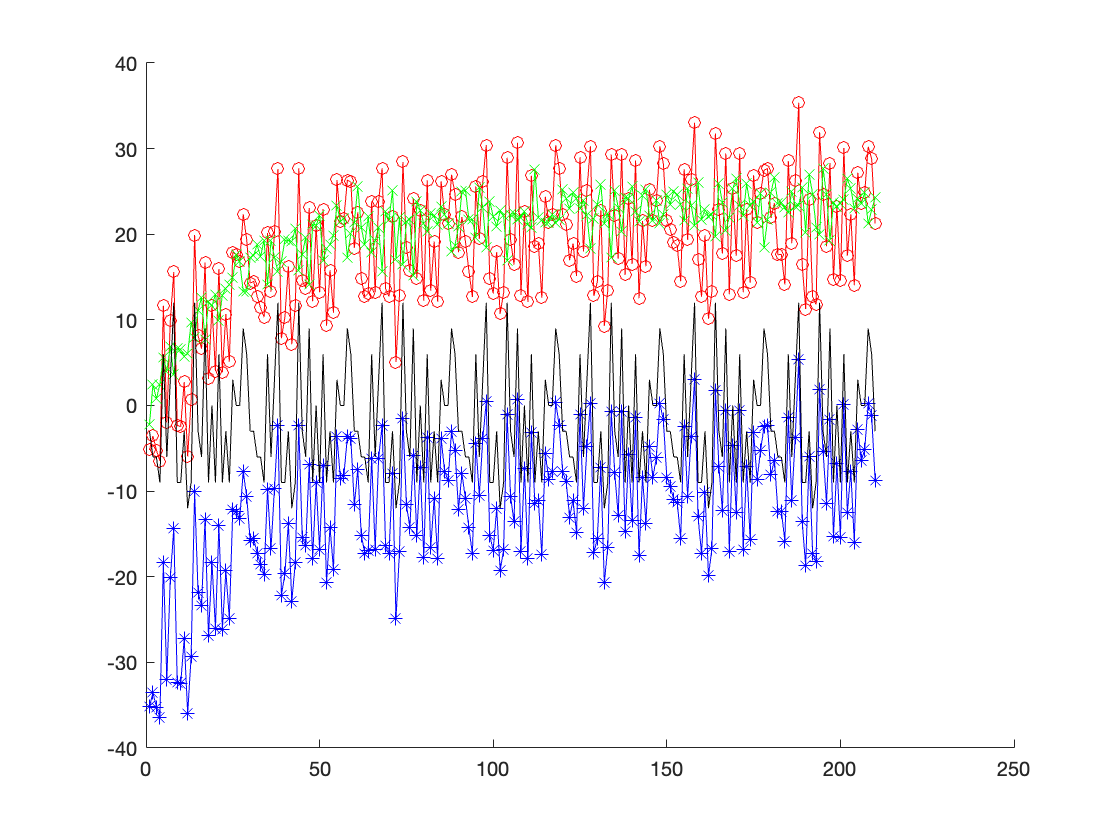

% Linear Sensory Recalibration Model of Implicit Adaptation. 
% Mengzhan Liufu, Jingyue Xu, Xueqian Deng, Chen Yang, Zhiguo Huang. Jan. 14 2022. 
% Adapted from Hadjiosif, A. M., Krakauer, J. W., & Haith, A. M. (2021). Did We Get Sensorimotor Adaptation Wrong? Implicit Adaptation as Direct Policy Updating Rather than Forward-Model-Based Learning. The Journal of Neuroscience, 41(12), 2747–2761. https://doi.org/10.1523/JNEUROSCI.2125-20.2021
% To see how simulated mirror-reversal adaptation varies with the width (σ) and learning rate (η) of the basis functions, and the saturation limit (A), select these parameters and click "Simulate". 
% 
% Simulate Sensory Recalibration Model of Implicit Adaptation. 
% Specify width of basis function

sigma =10;
eta =0.0001;
sat_limit =25;
seed_rng =48;

sigma_noise = 1.6;

rng (seed_rng); % fix randomization so simulations are reproducible

% initiate basis functions
delta_c = 0.05;
c = -60:delta_c:60;
u = -60:.5:60; 
w = zeros(size(c));
% proprio is the kernel of proprioception
% Learning (note that Ntrials is more than needed to simulate Experiment 2,
% which is 24 cycles (168 trials, i.e. 7 targets x 24 trials; and steady-state
% analysis uses cycles 13:24)
Ntrials = 210;

[u_out,y_out,te] = deal(NaN(1,Ntrials));

% Load targets used in experiments
t = cell2mat(struct2cell(load("targetdata210trials.mat")));
w_sat_limit = sat_limit*delta_c/sigma/sqrt(2*pi);

%basis functions
B = NaN(length(c),length(u));
for i=1:length(c)
    B(i,:) =  exp(-(u-c(i)).^2/(2*sigma^2));
end

u_map = NaN(Ntrials,length(u));

for i = 1:Ntrials
    u_map(i,:) = u + sigmoid_saturation(w,w_sat_limit) * B;
    
    [~,i_t] = min((u-t(i)).^2);
    
    u_out(i) = u_map(i,i_t) + sigma_noise * randn;
    
    % apply perturbation
    y_out(i) = u_out(i) - 30; % Rotation
    
    [~,i_selected] = min(abs(u-t(i)));
    
    %Task error
    [~,uOnline] = min((u-y_out(i)).^2);
    
    te(i) = -(u_map(i,uOnline) - u_out(i)); % convert to p prime
    
    % learning update
    w = w + eta * te(i) * B(:,i_selected)';
end

lins = lines;
figure; hold on;

% plot(te, '-o', 'Color', 'red');
plot(u_out, '-o', 'Color', 'red');
plot(u_out - t, '-x', 'Color', 'green');
plot(y_out, '-*', 'Color', 'blue');
plot(t, '-', 'Color', 'black');

function y = sigmoid_saturation(x,sat_limit)

y = sat_limit*erf(sqrt(pi)/2*x/sat_limit); end